# Estimating the Windchill Factor

## Introduction

On cold days, the wind makes the air feel colder than it actually is. The [windchill factor](https://www.weather.gov/safety/cold-faqs) predicts the perceived temperature and is an essential indicator to prevent frostbite in chilly areas. 

    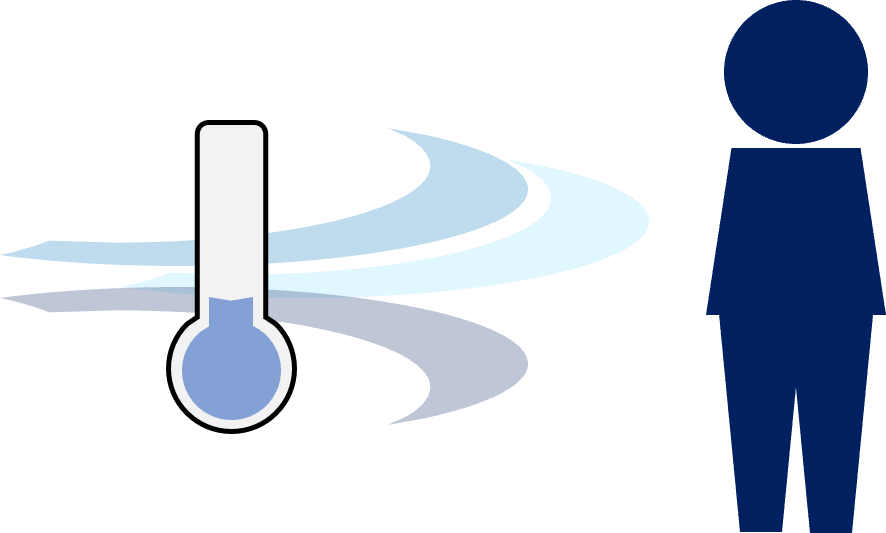

The factor is found by modeling the heat lost from a human face at different temperatures and wind speeds. An empirical equation is used to approximate these results:

        
$$T_{wc} = 35.74+0.6215\;T-35.75\;V^{0.16}+0.4275\;TV^{0.16}$$


where

- T is the air temperature in degrees Fahrenheit (°F)

- V is the wind speed in miles per hour (mph)

The equation is only valid when the actual air temperature is 50 °F or below, and the wind speed exceeds 3 miles per hour. 

## Task

In this exercise, you will write a function that calculates the wind chill temperature if the given temperature and wind speed are within the expected range. Otherwise, the function returns [Not a Number](https://www.mathworks.com/help/matlab/ref/nan.html) (`NaN`). In the **Function** section below, do the following:

- Declare a [function](https://www.mathworks.com/help/matlab/ref/function.html) named `windChill` with input variables `T` and `V` and output variable `Twc`.

- Add an [if-else](https://www.mathworks.com/help/matlab/ref/if.html) statement to check if `T` is less than or equal to 50, and `V` is greater than 3.

- When the if-condition is true, calculate the wind chill temperature using the provided equation and store the result in the variable `Twc`.

- When the if-condition is false, set the variable `Twc` equal to `nan`.

## **Code to Call Your Function** 

This section contains some test cases. Once you have written your function, run this section and inspect the results. Are the results what you expected?

% Test 1: if-condition is false
Twc1a = windChill(10,0)
Twc1b = windChill(60,10)
Twc1c = windChill(60,3)

% Test 2: if-condition is true
Twc2a = windChill(10,4)
Twc2b = windChill(50,10)

## Function

## Check your work

Is your function returning the expected results? 

The function should return `NaN` when `T>50` and/or `V<=3`.

- `Twc1a: NaN`

- `Twc1b: NaN`

- `Twc1c: NaN`

The function should return a value when `T<=50` and `V>3`.

- `Twc2a: 2.6638`

- `Twc2b: 46.0368`

Are your values different? If so, check the following:

- Declare the function using syntax similar to  `out1 = functionName(in1,in2)`.

- Use the logical AND operator ([&](https://www.mathworks.com/help/releases/R2024b/matlab/ref/double.and.html)) to combine the two relational operations for `T` and `V`.

- Double check your equation to make sure all the numbers and operators are exactly as shown in the equation above.

Need more help? Remember, you can ask questions in the course discussion forum.

## Conclusion

Congratulations on successfully completing this challenge activity! 

Continue your learning by using your function to compute the windchill temperature for $T=-10$ and $V=8$. Return to the course and submit your result in the corresponding question.

*Copyright 2025 The MathWorks, Inc.*